# ***E. coli***** BL21 FBA**

**By UCL iGEM 2020 **

**(Anna Su)**

## Initilization of COBRA

initCobraToolbox(false)



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2020
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.24.1).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configu

## Reading SBML & Outputing spreadsheet

%Read the original SBML of E. coli BL21 Genome Scale Metabolic Model 
%The model was downloaded from http://bigg.ucsd.edu/models/iECD_1391
original_BL21_model = readCbModel('iECD_1391 original.xml'); 

%prints out a spreadsheet containing all info in the model
outmodel = writeCbModel(original_BL21_model, 'xls', 'e.coli_BL21.xls'); 

## Making a Copy of the Original Model

%copy the original model. This ensures that no changes are made in the original model
modified_BL21_model = original_BL21_model;

## **Setting all Carbon uptake reactions to 0**

modified_BL21_model = changeRxnBounds(modified_BL21_model, 'EX_lipa_cold_e', 0, 'l'); 
modified_BL21_model = changeRxnBounds(modified_BL21_model, 'EX_cbl1_e', 0, 'l'); 
modified_BL21_model = changeRxnBounds(modified_BL21_model, 'EX_ac_e', 0, 'l'); 
modified_BL21_model = changeRxnBounds(modified_BL21_model, 'EX_for_e', 0, 'l');

## Setting a Base Model

base = modified_BL21_model;

## Adding metabolites and reactions in E. coli

pet_deg = base;

pet_deg = addMultipleMetabolites(pet_deg, ...
    {'PET[e]','PET[c]','MHET[c]','EG[c]','TPA[c]','TPA[e]'}, ...
    'metCharges', [ 0 0 0 0 0 0 ], 'metFormulas', ...
    {'C10H8O4','C10H8O4','C10H10O5','C2H6O2','C8H6O4','C8H6O4'})

pet_deg = struct with fields:
                                S: [1949×2741 double]
                             mets: {1949×1 cell}
                                b: [1949×1 double]
                           csense: [1949×1 char]
                             rxns: {2741×1 cell}
                               lb: [2741×1 double]
                               ub: [2741×1 double]
                                c: [2741×1 double]
                        osenseStr: 'max'
                            genes: {1333×1 cell}
                            rules: {2741×1 cell}
                        geneNames: {1333×1 cell}
                        compNames: {3×1 cell}
                            comps: {3×1 cell}
                         proteins: {1333×1 cell}
                       metCharges: [1949×1 double]
                      metFormulas: {1949×1 cell}
                         metNames: {1949×1 cell}
                        metHMDBID: {1949×1 cell}
                        metKEGGID: {19


%add PET exchange rxns
pet_deg = addReaction(pet_deg, 'PET_drain', 'PET[e] -> ''');
pet_deg = addReaction(pet_deg, 'PET_Transport', 'PET[e] -> PET[c]');

%add rxns PET -> MHET -> EG and MHET -> TPA as intracellular rxns
pet_deg = addReaction(pet_deg, 'PET', 'PET[c] + h2o[c] -> MHET[c]');
pet_deg = addReaction(pet_deg, 'MHET', 'MHET[c] + h2o[c] -> EG[c] + TPA[c]');

%add TPA exchange rxns
pet_deg = addReaction(pet_deg, 'TPA_Transport', 'TPA[c] -> TPA[e]');
pet_deg = addReaction(pet_deg, 'TPA_drain', 'TPA[e] -> ''');

%add intracellular rxns EG + NAD+ -> NADH + Glycolaldehyde 
pet_deg = addReaction(pet_deg, 'EG_gcald', 'EG[c] + nad[c] -> nadh[c] + gcald[c]');

## Optimizaton for E. coli growth on PET

pet = pet_deg;

%set the min glucose uptake flux to 0 (unit: mmol/gDCW/h)
pet = changeRxnBounds(pet, 'EX_glc__D_e', 0, 'l'); 

%sets the min PET uptake (unit: mmol/gDCW/h)
pet = changeRxnBounds(pet, 'PET_drain', -20, 'l'); 

%unlimited oxygen uptake (unit: mmol/gDCW/h)
pet = changeRxnBounds(pet, 'EX_o2_e', -20, 'l'); 

%optimization for growth
%gets the optimal BL21 biomass growth
biomass_PET = optimizeCbModel(pet, 'max') 

biomass_PET = struct with fields:
    origStatText: []
               f: 0.6543
               v: [2748×1 double]
               y: [1950×1 double]
               w: [2748×1 double]
               s: [1950×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.1639
           basis: []
          vars_v: []
               x: [2748×1 double]


%storing the optimal Z for BL21 biomass growth
biomass = biomass_PET.f; 

[FVA(:,1) FVA(:,2)] = fluxVariability(pet, [], [], pet.rxns);

## Optimization for TPA production

tpa = pet;
%Sets the both bounds of the biomass reaction to the optimal Z
tpa = changeRxnBounds(tpa, 'BIOMASS_Ec_iJO1366_core_53p95M', 0.2, 'b'); 

%Change the objective function to the reaction of TPA production
tpa = changeObjective(tpa, 'TPA_drain'); 

%optimization for TPA and get max flux
TPA_FBAsolutionMax = optimizeCbModel (tpa, 'max') 

TPA_FBAsolutionMax = struct with fields:
    origStatText: []
               f: 20
               v: [2748×1 double]
               y: [1950×1 double]
               w: [2748×1 double]
               s: [1950×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.2607
           basis: []
          vars_v: []
               x: [2748×1 double]



%get min flux
TPA_FBAsolutionMin = optimizeCbModel (tpa, 'min') 

TPA_FBAsolutionMin = struct with fields:
    origStatText: []
               f: 6.1269
               v: [2748×1 double]
               y: [1950×1 double]
               w: [2748×1 double]
               s: [1950×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.1789
           basis: []
          vars_v: []
               x: [2748×1 double]


## 3D plot: Growth vs Oxygen Uptake vs PET Uptake

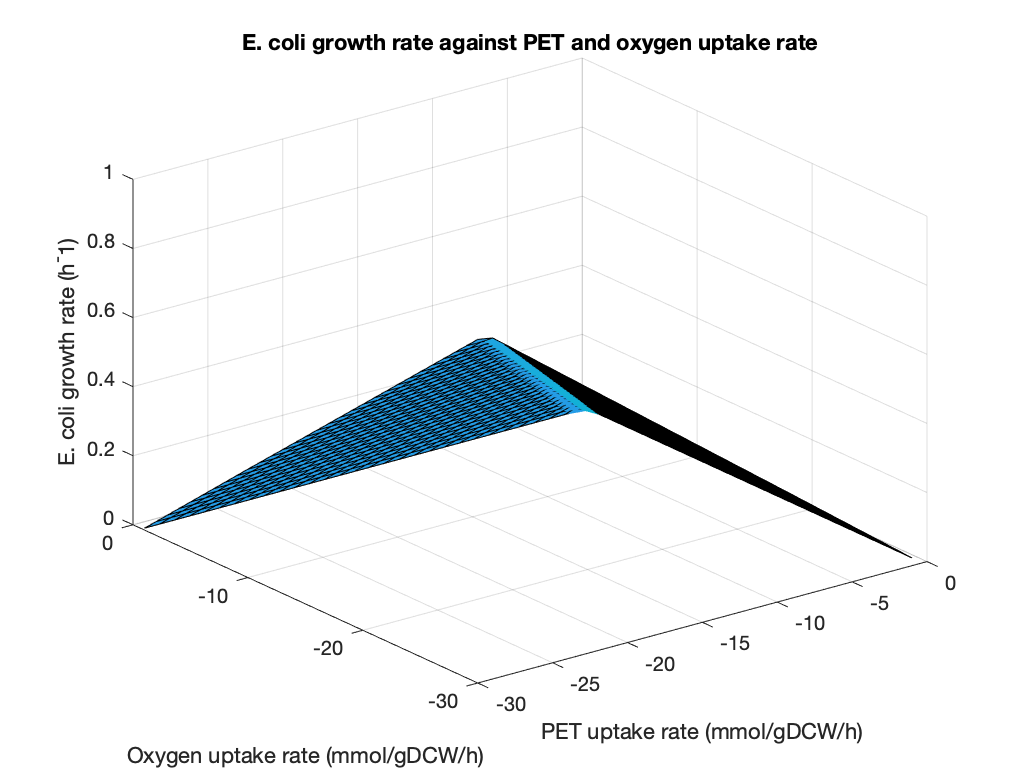

model_3Dplot = pet;
uptake = -[1:1:30];
oxygen = [1:1:30];
growth = zeros(30,30); 

for i = 1:30
    for j = 1:30
        model_3Dplot = changeRxnBounds(model_3Dplot, 'PET_drain', uptake(i), 'l'); 
        model_3Dplot = changeRxnBounds(model_3Dplot, 'EX_o2_e', -oxygen(j), 'l');      
        coli_FBAsolution = optimizeCbModel (model_3Dplot, 'max'); 
        growth(i,j) = coli_FBAsolution.f;  
    end
end

figure

surfl(uptake, -oxygen, growth');
xlabel('PET uptake rate (mmol/gDCW/h)');
ylabel('Oxygen uptake rate (mmol/gDCW/h)');
zlabel('E. coli growth rate (h^-1)')
title('E. coli growth rate against PET and oxygen uptake rate')

## 2D: Growth vs PET Uptake

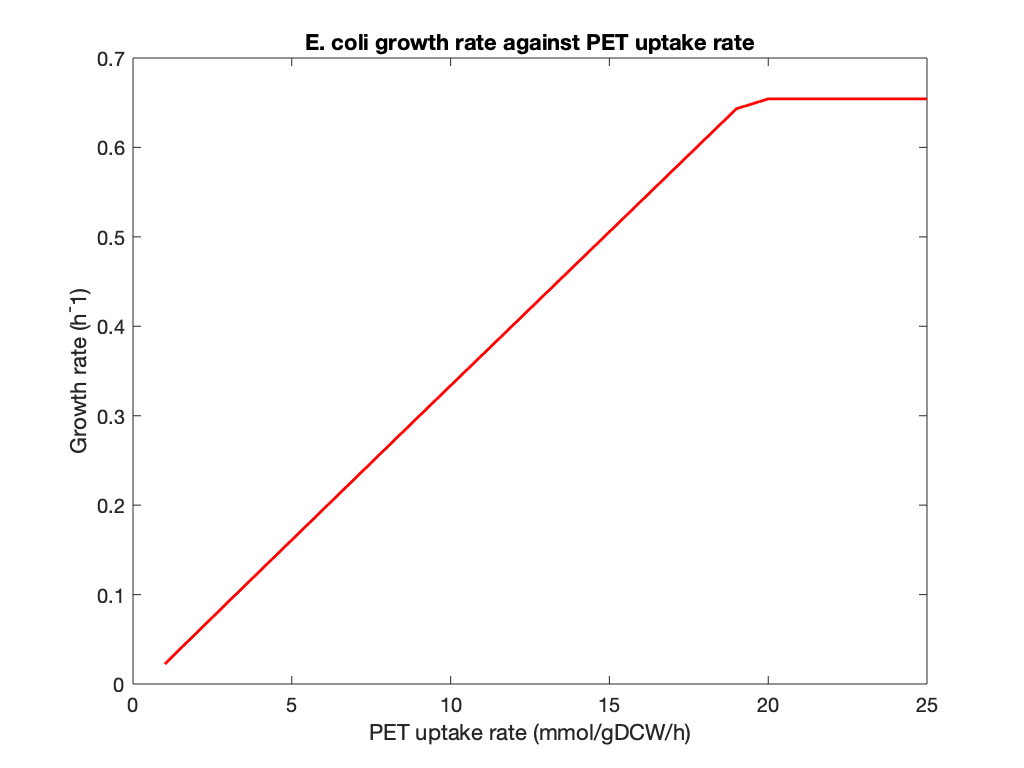

grow_plot = pet;
uptake = -[1:25];
growth = zeros(25,1);  

for i = 1:25
    grow_plot = changeRxnBounds(grow_plot, 'PET_drain', uptake(i), 'l');
    coli = optimizeCbModel (grow_plot); 
    growth(i) = coli.f;
end

figure
grid on
plot(-uptake, growth, 'r','LineWidth',1.4)

xlabel('PET uptake rate (mmol/gDCW/h)');
ylabel('Growth rate (h^-1)');
title('E. coli growth rate against PET uptake rate')

## 3D plot: TPA Production vs  PET Uptake vs Biomass Growth 

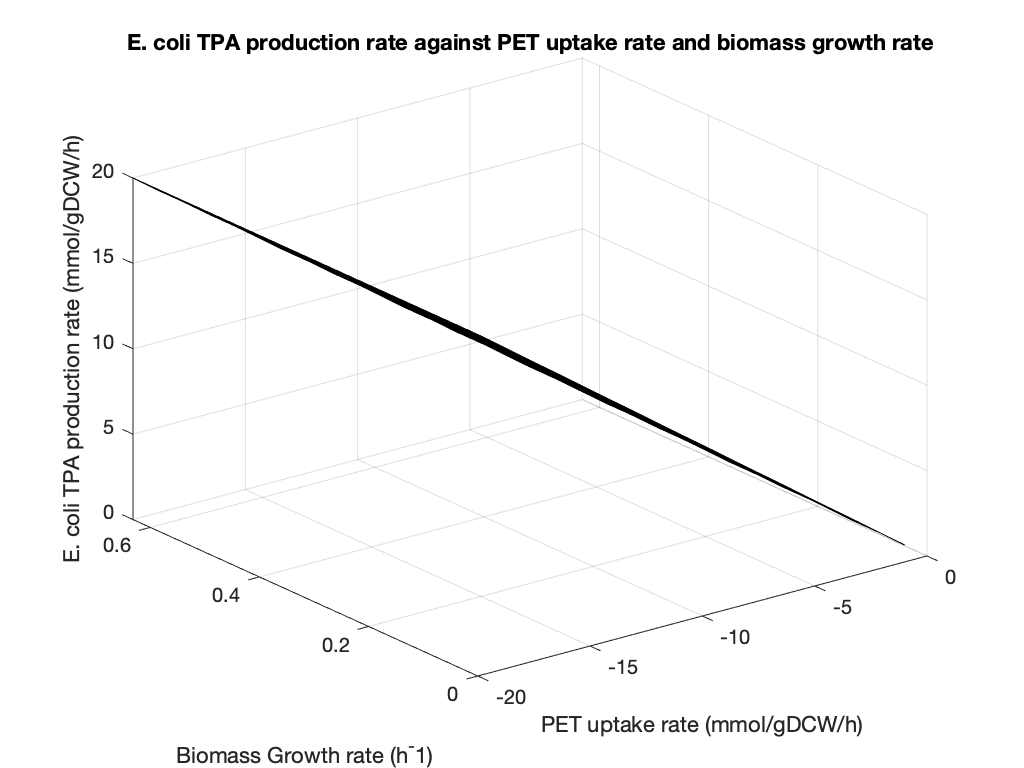

tpa_plot = pet;
PET_uptake = -[1:20];
growth = [0:1/19:1];
tpa_prod = zeros(20,20); 
tpa_plot = changeObjective(tpa_plot, 'TPA_drain'); 

for i = 1:20
    for j = 1:20
        tpa_plot = changeRxnBounds(tpa_plot, 'PET_drain', PET_uptake(i), 'l'); 
        tpa_plot = changeRxnBounds(tpa_plot, 'BIOMASS_Ec_iJO1366_core_53p95M', growth(j), 'l');      
        tpa_solution = optimizeCbModel (tpa_plot, 'max'); 
        tpa_prod(i,j) = tpa_solution.f;  
    end
end

figure

surfl(PET_uptake, growth, tpa_prod');
xlabel('PET uptake rate (mmol/gDCW/h)');
ylabel('Biomass Growth rate (h^-1)');
zlabel('E. coli TPA production rate (mmol/gDCW/h)')
title('E. coli TPA production rate against PET uptake rate and biomass growth rate')

## Sinlge Gene Deletion

model_SGD = pet;
model_SGD = changeRxnBounds(model_SGD, 'PET_drain', -20, 'l'); 
model_SGD = changeRxnBounds(model_SGD, 'BIOMASS_Ec_iJO1366_core_53p95M', 0.2, 'l');
model_SGD = changeRxnBounds(model_SGD, 'BIOMASS_Ec_iJO1366_core_53p95M', 0.3, 'u');
model_SGD = changeObjective(model_SGD, 'TPA_drain');
[prodRatio, prodRateKO, prodRateWT, hasEffect, delRxns, fluxSolution] = singleGeneDeletion(model_SGD);

Single gene deletion analysis in progress ...
100%    [........................................]



max(prodRateKO)

ans = 20

## Pathways of PET Degradation 

Exogenous pathway: PET -> MHET -> EG -> gcald

Innate pathway:  glycoaldedyde (GA) -> glycolate (GC) -> glycoxalate (GLA) - > tartronate semialdehyde (TS) -> glycerate (GL) 

                     -> 3-phosphoglycerate (3PG) -> 2-phosphoglycerate (2PG) -> phosphoenolpyruvate (PEP) -> Pyruvate (Pyr)

rxnID                            rxnName                                 formula     

1241        glycolaldehyde dehydrogenase              GA -> GC

1373        glycolate oxidase                                    GC -> GLA

1322        glyoxalate carboligase                            GLA -> TS

2458        tartronate Semialdehyde reductase        TS -> GL

1355        glycerate kinase                                      GL -> 3PG

1988        phosphoglycerate mutase                       3PG -> 2PG

990          enolase                                                    2PG -> PEP

2221        pyruvate kinase                                       PEP -> Pyr

%double checking
innate_rxn_ID = [1241, 1373, 1322, 2458, 1355, 1988, 990, 2221];
innate_rxn_fullName = original_BL21_model.rxnNames(innate_rxn_ID)
innate_rxn_abbreviations = original_BL21_model.rxns(innate_rxn_ID)
innate_rxn_formula = printRxnFormula(original_BL21_model,innate_rxn_abbreviations);

## Checking against literature

glucose = modified_BL21_model;
%set the min glucose uptake flux to 0 (unit: mmol/gDCW/h)
glucose = changeRxnBounds(glucose, 'EX_glc__D_e', -9.2, 'l'); 
glucose = changeRxnBounds(glucose, 'EX_glc__D_e', -7.6, 'u'); 

%unlimited oxygen uptake (unit: mmol/gDCW/h)
glucose = changeRxnBounds(glucose, 'EX_o2_e', -13.1, 'l'); 
glucose = changeRxnBounds(glucose, 'EX_o2_e', -10.7, 'u'); 

%Warning: MATLAB crashed when I ran these:
%optimization for biomass and get max flux
BiomassGLC_Max = optimizeCbModel (glucose, 'max') 

BiomassGLC_Max = struct with fields:
    origStatText: []
               f: 0.7847
               v: [2741×1 double]
               y: [1943×1 double]
               w: [2741×1 double]
               s: [1943×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.3243
           basis: []
          vars_v: []
               x: [2741×1 double]


%get min flux
BiomassGLC_Min = optimizeCbModel (glucose, 'min')

BiomassGLC_Min = struct with fields:
    origStatText: []
               f: 0
               v: [2741×1 double]
               y: [1943×1 double]
               w: [2741×1 double]
               s: [1943×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.1374
           basis: []
          vars_v: []
               x: [2741×1 double]
